clear;clc;close all;
snr = 25;
mod_data = qammod([0 1 2 3 2 1 0;0 1 2 3 2 1 0;0 1 2 3 2 1 0],4)';
mod_data_ch = awgn(mod_data,snr);
[nfft,ofdm_symbols] = size(mod_data);
for i = 1:ofdm_symbols
    for k=1:nfft
        EVM(k,i) = sqrt((imag(mod_data_ch(k,i))-imag(mod_data(k,i)))^2+(real(mod_data_ch(k,i))-real(mod_data(k,i)))^2);
    end
end
EVM

EVM =     0.0587    0.0182    0.0575
    0.0663    0.0644    0.0669
    0.0316    0.0511    0.1032
    0.0115    0.0434    0.0187
    0.0919    0.1125    0.0758
    0.0328    0.0298    0.0402
    0.0120    0.1087    0.0641


EVM_DB = 20*log10(EVM)

EVM_DB =   -24.6203  -34.7807  -24.7994
  -23.5754  -23.8271  -23.4962
  -29.9979  -25.8245  -19.7242
  -38.7597  -27.2550  -34.5400
  -20.7365  -18.9775  -22.4039
  -29.6777  -30.5044  -27.9100
  -38.3999  -19.2770  -23.8678


max(EVM_DB)

ans =   -20.7365  -18.9775  -19.7242


mean(mean(EVM_DB))

ans = -26.8074

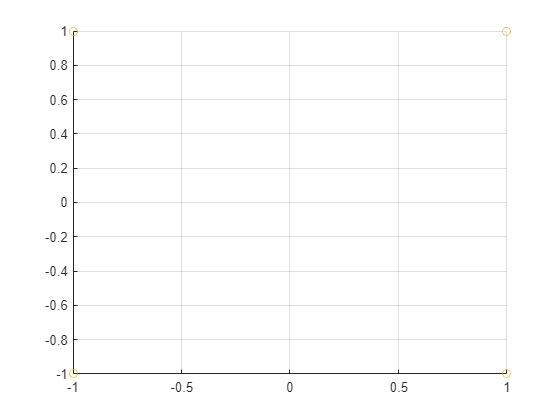

figure(),scatter(real(mod_data),imag(mod_data)),grid on

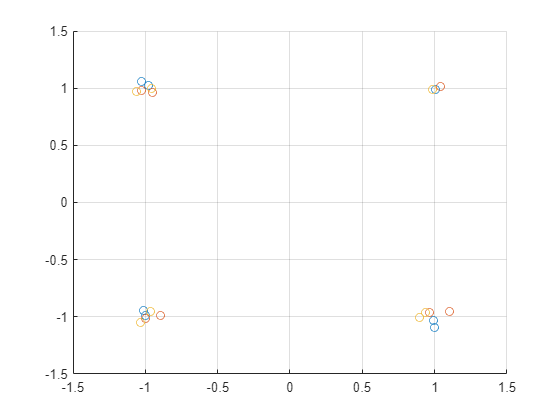

figure(),scatter(real(mod_data_ch),imag(mod_data_ch)),grid on